clc;clear;close all;

## 读取点

warning off
[num,txt,raw] = xlsread("e.xls");
x = num(8,~isnan(num(8,:)));
y = num(9,~isnan(num(9,:)));
z = num(7,~isnan(num(7,:)));
azimuth = num(4,1);
elevation = num(4,2);
Points = [x;y;z];

PAB = Points(:,5);
P1 = num(1,[3,4,2]);
P2 = num(2,[3,4,2]);

## 复测数据

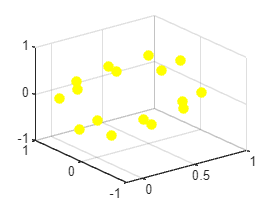

xx = num(13,~isnan(num(13,:)));
yy = num(14,~isnan(num(14,:))); 
zz = num(12,~isnan(num(12,:)));
PointFC = [xx;yy;zz];
scatter3(xx,yy,zz,50,'filled','yellow')

## 拟合圆柱

[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Points,P1,P2);

## A、B面点测试

numShengLu = 4;
phi = pi/4;

toff = zeros(1,2*numShengLu);
roff = zeros(1,2*numShengLu);

Ang = ShengLuJiaoJiSuan(numShengLu)

Ang =     0.9425    0.3142   -0.3142   -0.9425   -0.9425   -0.3142    0.3142    0.9425



[PointTable_A_off,PointTable_B_off] = Calculat_A_and_B_Points_after_Offest2(MTaon',Mcenter',Mradial,PAB,phi,Ang,toff,roff)

PointTable_A_off =    -0.1418    0.1555    0.5263    0.8290    0.8377    0.5404    0.1696   -0.1331
    0.7295    1.0401    1.0434    0.7380   -0.2587   -0.5693   -0.5726   -0.2672
    0.2912    0.3034    0.3034    0.2912    0.2518    0.2396    0.2396    0.2518


PointTable_B_off =    -0.1376    0.1623    0.5331    0.8332    0.8335    0.5336    0.1628   -0.1373
    0.2508    0.2656    0.2689    0.2593    0.2200    0.2052    0.2019    0.2115
   -0.2269   -0.5349   -0.5349   -0.2269    0.7699    1.0779    1.0779    0.7699


## 复测函数

[Distance,theta,LTPY,TiC,Wquanzhong1,Wquanzhong2]=YuanXingFuCe(PointFC,numShengLu,Mcenter,MTaon,Mradial,phi)

Distance =     0.9125    1.5655    1.5653    0.9151


theta =     0.7688    0.7806    0.7800    0.7722


LTPY =     0.0810    0.0455    0.0488    0.0776


TiC =    -0.8133   -0.3166    0.3167    0.8129


Wquanzhong1 =     0.3601
    0.6074
    0.6065
    0.3603


Wquanzhong2 =     0.3559
    0.6084
    0.6077
    0.3560


## 绘图验证

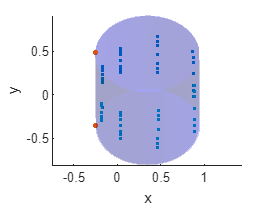

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
scatter3(Points(1,:),Points(2,:),Points(3,:),5,"filled");
scatter3([P1(1),P2(1)],[P1(2),P2(2)],[P1(3),P2(3)],10,"filled");


PointTable_A_off = PointTable_A_off';
PointTable_B_off = PointTable_B_off';
% scatter3(PointTable_A_off(:,1),PointTable_A_off(:,2),PointTable_A_off(:,3),20,'filled','yellow')
% scatter3(PointTable_B_off(:,1),PointTable_B_off(:,2),PointTable_B_off(:,3),20,'filled','yellow')